# ***FORGROUND AND BACKGROUND EXTRACTION***

**DONE BY **

**ROHITH RAVI CB.SC.U4AIE24350**

**AKHILAN CB.SC.U4AIE24362**

**APARNA CB.SC.U4AIE24304**

**POORNIMA CB.SC.U4AIE24343**

## *Abstract*

This paper presents a very initiative foreground and background extraction from a static camera scene using ***Robust Principal Component Analysis (RPCA)***. The method leverages the ***Augmented Lagrange Multiplier Method (ADMM)*** to decompose an image into two matrices: a ***low-rank matrix (L)*** representing the background part of the image, and a ***sparse matrix (S)*** representing the foreground objects. The low-rank component captures the recurring, consistent elements of the scene, while the sparse component isolates the dynamic, transient changes. The ADMM algorithm is an ***iterative optimization approach*** that efficiently. The presented code demonstrates this by ***processing a grayscale image***, where the background (the static scene) is modeled as the low-rank component and the foreground (the subject, in this case, a person) is the sparse component. The iterative process is shown to converge quickly, with the reconstruction error decreasing significantly over each iteration, demonstrating the method's effectiveness in separating the two components. The final output provides a clear, ***thresholded binary mask of the foreground (***A ***threshold binary mask*** is a binary image (consisting of only black and white pixels) created by applying a thresholding technique to a grayscale image), highlighting the precise shape of the object.    

##                                                                                            
$$\begin{array}{l}
\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{UPDATE}\;\mathrm{EQUATIONS}\\
\\
\\
\\
\\
L\left(L,S,Y,\mu \right)\Rightarrow \parallel L\parallel \ast +\lambda \parallel S\parallel 1+\left\langle Y,L+S-M\right\rangle +\frac{\mu }{2}\parallel L+S-M\parallel_2 \\
\\
\mathrm{Substitution}\;\mathrm{of}\;\mathrm{Residual}\;R:\\
\;\\
R=L+S-M\\
\\
\mathrm{Terms}\;\mathrm{to}\;\mathrm{be}\;\mathrm{multiplied}:\\
\\
\parallel L\parallel_* +\lambda \parallel S\parallel_1 +\left\langle Y,R\right\rangle +\frac{\mu }{2}{||R||}_2^2 \\
\\
\mathrm{Completing}\;\mathrm{the}\;\mathrm{Square}\;\mathrm{on}\;\mathrm{Penalty}/\mathrm{Dual}\;\mathrm{Terms}:\\
\\
\left\langle Y,R\right\rangle +\frac{\mu }{2}{||R||}_2^2 =\frac{\mu }{2}\left\lbrack {||R||}_2^2 +\frac{2}{\mu }\left\langle Y,R\right\rangle \right\rbrack \\
\\
\left(\mathrm{After}\;\mathrm{Completing}\;\mathrm{the}\;\mathrm{Square}\;\mathrm{and}\;\mathrm{collecting}\;\mathrm{terms}\right)\\
\\
=\frac{\mu }{2}\left\lbrack {||R||}_2^2 +\frac{2}{\mu }\left\langle Y,R\right\rangle \right\rbrack -\frac{1}{2\mu }{||Y||}_2^2 \\
\\
\mathrm{Substitution}\;\mathrm{of}\;R\;\mathrm{back}\;\mathrm{into}\;\mathrm{the}\;\mathrm{Squared}\;\mathrm{Term}:\\
\\
=\frac{\mu }{2}{||L+S-M+\frac{Y}{\mu }||}_2^2 -\frac{1}{2\mu }{||Y||}_2^2 \\
L-\mathrm{Update}\;\mathrm{Subproblem}\left(\mathrm{Minimization}\right):\\
\\
L_{k+1} =\arg_L \min \left\lbrace \parallel L\parallel_* +\left\lbrack {||L+S^k -M+\frac{Y^k }{\mu }||}_2^2 \right\rbrack \right\rbrace \\
\\
\mathrm{Defining}\;\mathrm{the}\;\mathrm{Matrix}\;Q\;\mathrm{for}\;\mathrm{Simplification}:\\
\\
Q^k =M-S^k -\frac{Y^k }{\mu }\\
\\
\mathrm{Simplified}\;L-\mathrm{Update}\;\mathrm{subproblem}\;\left(\mathrm{Solvable}\;\mathrm{by}\;\mathrm{SVT}\right)\\
\\
L^{k+1} =\arg_L \min \left\lbrace \parallel L\parallel^* +\frac{\mu }{2}{||L-Q^k ||}_2^2 \right\rbrace \\
\;\;\;\;\;\;\;\;\;\\
L^{k+1} ={\mathrm{SVT}}_{\frac{1}{\mu }} \left(Q^k \right)\\
\\
\mathrm{Singular}\;\mathrm{Value}\;\mathrm{Thresholding}\;\mathrm{takes}\;\mathrm{place}\ldotp \\
\;\\
\Rightarrow L^{k+1} ={\mathrm{SVT}}_{\frac{1}{\mu }} \left(M-S^k -\frac{Y^k }{\mu }\right)\\
\mathrm{Update}\;S^{k+1\;} :\\
\\
\left.S^{k+1} =\arg_S \min \left\lbrace \lambda \parallel S\parallel_1 +{\left\lbrack \frac{\mu }{2}||S-\left(M-L^{k+1} +\frac{Y^k }{\mu }\right)||\right.}_2^2 \right\rbrack \right\rbrace \\
\\
\mathrm{Let}\;X=M-L^{k+1} -\frac{Y^k }{\mu }\left(\mathrm{or}\;M-L^{k=1} +\frac{Y^k }{\mu }\mathrm{based}\;\mathrm{on}\;\mathrm{sign}\;\mathrm{conventions}\right)\\
\\
\mathrm{Similar}\;\mathrm{to}\;L,\mathrm{when}\;\mathrm{we}\;\mathrm{try}\;\mathrm{to}\;\mathrm{solve}\;\mathrm{it}:\\
\\
S^{k+1} =\arg_S \min \left\lbrace \lambda \parallel S\parallel_1 +\frac{\mu }{2}{||S-X||}_2^2 \right\rbrace \\
\;\\
S^{k+1} =\mathrm{shrink}\left(M-L^{k+1} +\frac{Y^k }{\mu }\right)\;\mathrm{or}\;\mathrm{soft}\;{\mathrm{Thresholding}}_{\frac{\lambda }{\mu }} \left(M-L^{k+1} +\frac{Y^k }{\mu }\right)\\
\\
Y\;\mathrm{Update}\;\mathrm{Equation}:\\
\\
Y^{k+1} =Y^k +\mu \left(L^{k+1} +S^{k+1} -M\right)\\

\end{array}$$


***A function*** here is to separate foreground and background using ADMM

function [L, S] = separate_foreground_background(M, lambda_val, max_iter, tol)
    
    [m, n] = size(M);
    
    if nargin < 4
        tol = 1e-7;
    end
    if nargin < 3
        max_iter = 500;
    end
    if nargin < 2 || isempty(lambda_val)
        lambda_val = 1.0 / sqrt(max(m, n));
    end

    L = zeros(m, n);
    S = zeros(m, n);
    Y = zeros(m, n);
    
    % As suggested in literature
    mu = 1.25 / norm(M, 2); 
    mu_max = mu * 1e7;
    rho = 1.5; % Multiplier for mu

    fprintf('Starting ADMM for Foreground/Background Separation...\n');

***the for loop*** *is for the update equations.  *      

    
    for i = 1:max_iter
        % Step 1: Update L (Low-Rank Matrix)
        [U, s, V] = svd(M - S + Y / mu, 'econ');
        s_thresh = max(diag(s) - 1/mu, 0);
        L = U * diag(s_thresh) * V';

        % Step 2: Update S (Sparse Matrix)
        S_unthresh = M - L + Y / mu;
        S = sign(S_unthresh) .* max(abs(S_unthresh) - lambda_val / mu, 0);

        % Step 3: Update Y (Lagrange Multiplier)
        Y = Y + mu * (M - L - S);

        % Step 4: Update mu
        mu = min(mu * rho, mu_max);

        % Calculate and display reconstruction error
        error = norm(M - L - S, 'fro') / norm(M, 'fro');
        fprintf('Iteration %d: Reconstruction Error = %.6f\n', i, error);

        % Check for convergence
        if error < tol
            break;
        end
    end

    fprintf('\nADMM finished.\n');
end

1. *Reading and preprocessing the image*

image = imread("D:\Sem 3\MFC sem 3\Project Files\simple_image.jpg");
gray_image = rgb2gray(image);
normalized_image = im2double(gray_image);

2. *Separating foreground and background*

[background_L, foreground_S] = separate_foreground_background(normalized_image, [], 40, 1e-7);

Starting ADMM for Foreground/Background Separation...
Iteration 1: Reconstruction Error = 0.809391
Iteration 2: Reconstruction Error = 0.204901
Iteration 3: Reconstruction Error = 0.204901
Iteration 4: Reconstruction Error = 0.162720
Iteration 5: Reconstruction Error = 0.116214
Iteration 6: Reconstruction Error = 0.092895
Iteration 7: Reconstruction Error = 0.071157
Iteration 8: Reconstruction Error = 0.055722
Iteration 9: Reconstruction Error = 0.037115
Iteration 10: Reconstruction Error = 0.022323
Iteration 11: Reconstruction Error = 0.014576
Iteration 12: Reconstruction Error = 0.010160
Iteration 13: Reconstruction Error = 0.007076
Iteration 14: Reconstruction Error = 0.004911
Iteration 15: Reconstruction Error = 0.003391
Iteration 16: Reconstruction Error = 0.002349
Iteration 17: Reconstruction Error = 0.001616
Iteration 18: Reconstruction Error = 0.001114
Iteration 19: Reconstruction Error = 0.000764
Iteration 20: Reconstruction Error = 0.000515
Iteration 21: Reconstruction Error 

 3. *Converting back to displayable image formats*

background_img = im2uint8(background_L);
foreground_img = im2uint8(abs(foreground_S));


 4. *Thresholding the foreground to create a binary mask*

foreground_thresh = imbinarize(foreground_img, 30/255);

5. *Displaying the results*

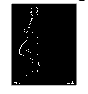

figure;
imshow(foreground_thresh);
title('Extracted Foreground');